ToM 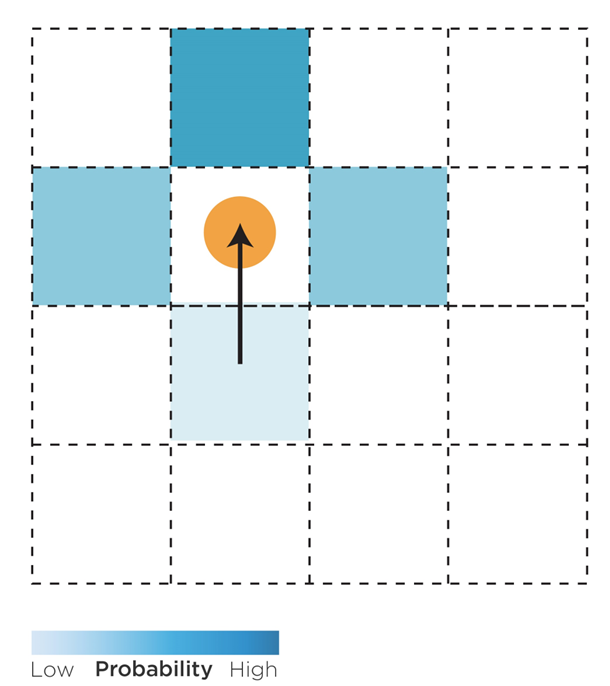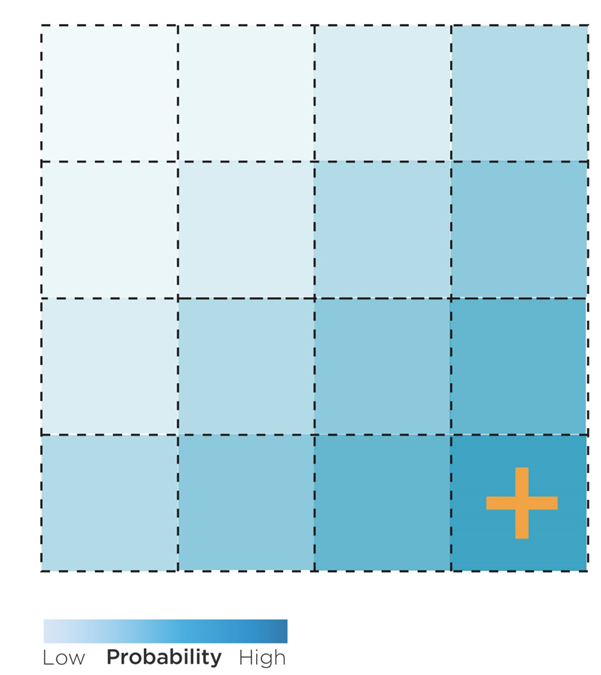

## Create a 4x4 graph as TCG environment

`Here we create a TCG game environment by using the 2d matlab graph function. The graph has 16 nodes with corresponding transitions. Transitions are created in a way that we get a 4x4 grid object as it is displayed on the plot. `

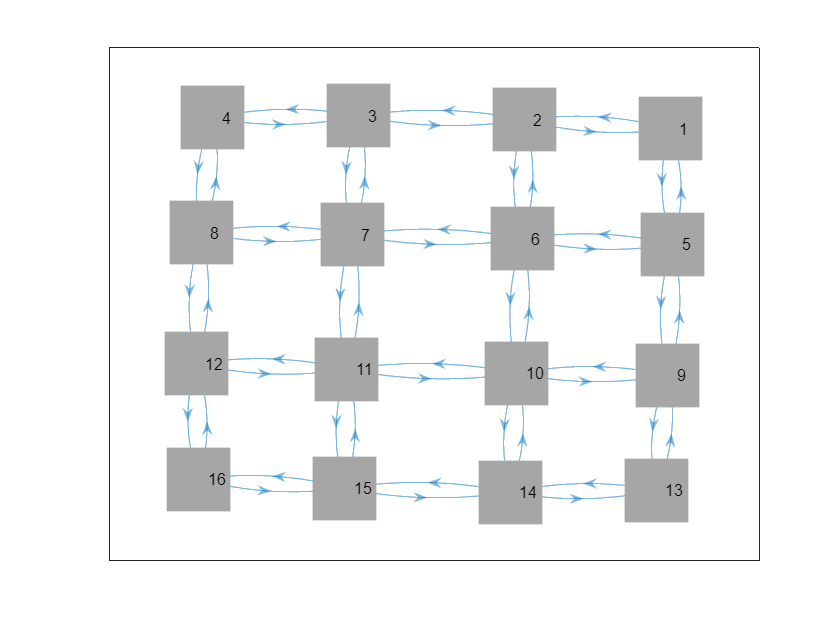

clear all; close all; clc
s = [1 1 2 2 2 3 3 3 4 4 5 5 5 6 6 6 6 7 7 7 7 8 8 8 ...
    9 9 9 10 10 10 10 11 11 11 11 12 12 12 13 13 14 14 14 15 15 15 16 16]; % create nodes
t = [2 5 1 3 6 2 4 7 3 8 1 6 9 2 5 7 10 3 6 8  11 4 7 12 5 10 13 6 9 11 14 ...
    7 10 12 15 8 11 16 9 14 10 13 15 11 14 16 12 15]; % create edges
G = digraph(s,t); % create a graph
p=plot(G,'NodeColor', [0.6510    0.6510    0.6510]);
p.Marker = 's';
p.MarkerSize =40;

## Goal configuration, Parameters and State priors

### **1) Goal configuration**

`Here we define goal congifuration for a trial: sender's goal (goal_s), receiver's goal(goal_r) and start position(start), represented on the plot with red, orange, and blue colors, respectivly.`

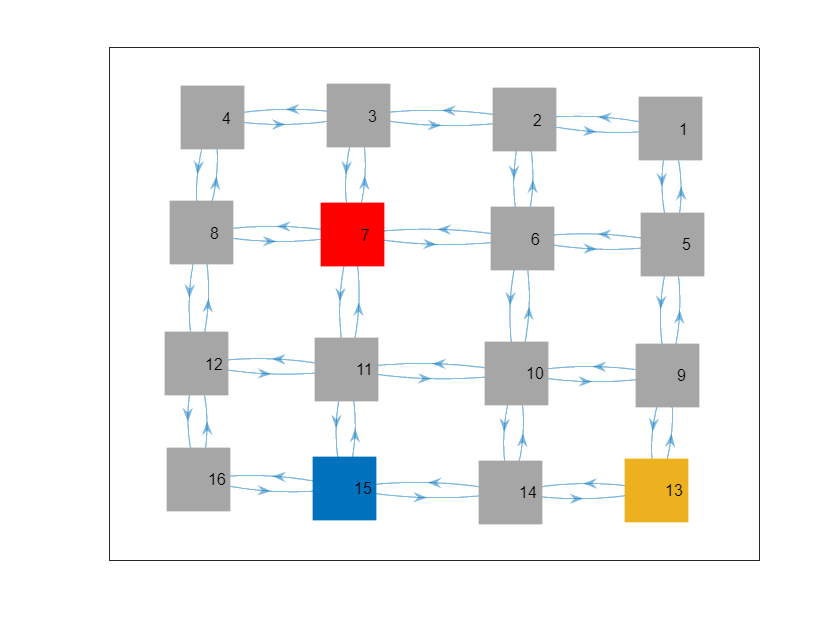

start=7;
current_state=start;
goal_r=15;
goal_s=13;

p=plot(G,'NodeColor', [0.6510    0.6510    0.6510]);
p.Marker = 's';
p.MarkerSize =40;
highlight(p,start,'NodeColor','red')
highlight(p,goal_r,'NodeColor',[0 0.4470 0.7410])
highlight(p,goal_s,'NodeColor',[0.9290 0.6940 0.1250])

### 2) Model parameters

`We have 5 model parameters that need to be estimated: `

- `alpha -` ** positive estimable slope parameter, determining the rate at which probabilities decrease with increasing distance from the Sender’s goal**`.`

- `lambda - probability of going backwards `$p(backwards)$

- `gamma - odds ratio between `$p(forward)/p(turn)$

- `tau - model temperature`

- `epsilon - used to calculate discount factor for the reward`

params=[2,0.001,4,10,0.6]; 
[alpha,lambda,gamma,tau,epsilon]= deal(params(1), params(2), params(3),params(4),params(5));

### 3) State priors

`State priors play a crucial role in providing a general sense of the Sender's goal or destination. Specifically, the prior state probability is a function that has a value of 1 at the Sender's goal and then decreases according to an inverse power rule as the distance from the goal increases.`

`The function is defined as p(s)=1 / (a^d)   where p(s) is the probability of a state being at distance d from the Sender’s goal location.   a is the positive estimable slope parameter, determining the rate at which probabilities decrease with increasing distance from the Sender’s goal. It remains constant for all trials, but the location of the peak of the state prior changes with every goal configuration. `

`State prior probabilities are used twice in the model later on. First, to combine it with the action prior probabilities in the planning phase 1, and second, to plan the second phase of the path entirely.`

state_priors=set_state_prior(G,goal_s,alpha);
%normilized_state_priors=normalize(state_priors);
disp(['state prior probabilities: [' num2str(state_priors(:,2).') ']']) ;

state prior probabilities: [0.125      0.0625     0.03125    0.015625        0.25       0.125      0.0625     0.03125         0.5        0.25       0.125      0.0625           1         0.5        0.25       0.125]


# ***Main loop***

## Planning phase 1

`In the planning phase 1 the model uses value iteration to plan the next action untill a certain planning horizon is reached. The agent would generate or roll out a policy tree and then calculate the expected values of the next actions using the value calculated at the diﬀerent planning steps, but importantly, with a discounted reward at possible future states (the planning horizon can be used as the discount factor here). For instance, with a planning horizon of 2, the agent would plan 3 steps into the future (0, 1, and 2). At the ﬁrst step (horizon 0), the agent would calculate expected values for each available action using action or state-action model and the reward at the next state. Then, at the second step (horizon 1), the agent repeats these calculations for each of the next states. And at the third step (horizon 2), the same procedure repeats for the state after the next state. Then, the agent would calculate the sum of the expected values along each trajectory in the policy tree.The ﬁnal action probabilities for the actions  available in the current states are calculated by softmax’ing these sums of future expected rewards.`

### 1) roll-out the policy tree and generate the paths

`Here the agent generates the policy tree with specified planning horizon (h=3).  In the first iteration holizon step (n_steps) is 1, which means agent looks one step ahead in the future. The agent rolls-out policy tree with n-step size and looks at the resulted paths. If thtere are paths which at some point had reached receiver's goal location then the agent selectes those paths (selected_paths) it there are no such paths in the tree then the agent selected all the paths for the next steps. `

planned_path_phase1=start;
msg_step=0; 
previous_state=start;
h=2;
while previous_state~=goal_r
    selected_paths={};
    for n_steps=1:h
        paths=roll_out_policy_tree(G,current_state,n_steps);
        [row,col]= find(paths==goal_r);
        for i=1:length(row)
            selected_paths{end+1,1}=paths(row(i),:);
        end
    end
    if isempty(selected_paths)
        selected_paths=num2cell(paths,2);
    end

 

action_probabilities = 1

action_probabilities = 1

action_probabilities =     1.0000    0.0000    0.0000


###  2) calculate expected values for each path

`For every path in the selected path the following is done: 1) ``(Function name: set_action_priors) ``For every step in a path action prior pribabilities are  calculated by the idea of movmenet kinetics `$p(forward) > p(left) = p(right) > p(backward)$`.2) ``(Function name: normalize_action_priors) ``Calculated action priors then are combined with state prior pribabilities that provides the general sence of direction towards sender's goal location. 3)``(Function name: set_expected_values) `` these combined state-action priors are then used to calculate the expected values by taking the log of the negative state-action values and scale it with the discounted reward.4) ``(Function name: sum)``The values calculated for each step is then summed up and we have the value of the entire path. So if we have 21 selected path (paths that at some point reach receiver's goal location) then we will have 21 expected values. `

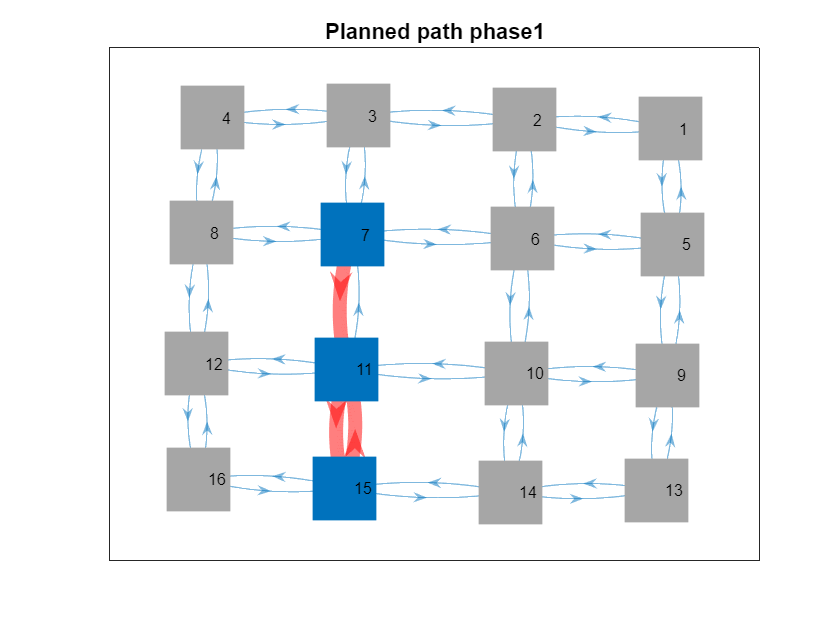

    sums_of_expected_values=[];next_states=[];
    for j=1:length(selected_paths)
        path=selected_paths{j,:};
        s=path(1:end-1);
        s2=path(2:end);

        for i=1:length(s)
            transition_states=successors(G,s(i));
            [action_prior]=set_action_priors(s,i,transition_states,lambda,gamma);
            action_state_priors=normalize_action_priors(state_priors,transition_states,action_prior);
            expected_value=set_expected_values(i,msg_step,action_state_priors,transition_states,G,goal_s,goal_r,epsilon);
            path_expected_values(i)=expected_value(transition_states==s2(i));
        end
        sums_of_expected_values(j)=sum(path_expected_values) ;
        next_states(j)=path(2);
    end

action_probabilities =     0.0665
    0.4335
    0.0665
    0.4335


action_probabilities =     0.0225
    0.9551
    0.0225


action_probabilities =     0.0006
    0.9989
    0.0006


###  3) make the probabilistic action selection based on the calculated expected values

`The ﬁnal action probabilities for the actions  available in the current state are calculated by softmaxing these sums of future expected values/rewards` `(function name: calculate_action_probabilities)``. ``Parameter tau is model tempriture that determines how much influence the value difference have on the final choice.`

`So that the agent chooses where to move from the current state and we update the status of the current state and after that the whole proccess starts over till we reach receiver's goal location. `

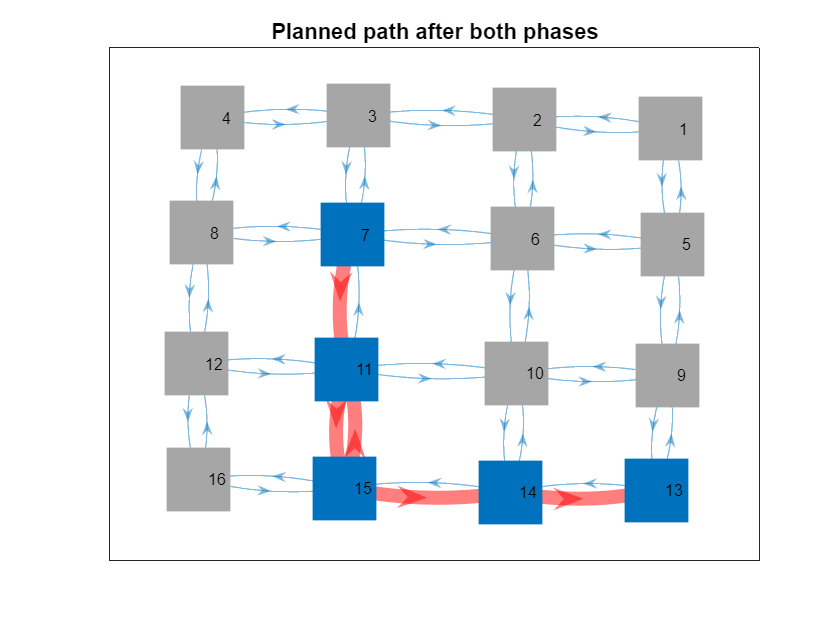

    values_of_next_actions=[];
    next_states_unique = unique(next_states);
    for n=1:length(next_states_unique)
        selected_values= sums_of_expected_values(next_states==next_states_unique(n));
        values_of_next_actions(n)=sum(selected_values);
    end
    action_probabilities=calculate_action_probabilities(values_of_next_actions,tau);

    choice=make_choices(action_probabilities,next_states_unique);
    current_state=choice;
    planned_path_phase1(end+1)=current_state;
    previous_state=planned_path_phase1(end-1);
    msg_step=msg_step+1;
end

`Once we reach the reciever's goal location and step out from there the whole loop is over and we have the first part of the path planned.`

`On the plot you can see the planned path from the first planning phase. visited locations are shown with blue node and directions are shows with red arrows.`

p=plot(G,'NodeColor', [0.6510    0.6510    0.6510]);
p.Marker = 's';
p.MarkerSize =40;
highlight(p,planned_path_phase1,'NodeColor',[0 0.4470 0.7410],'EdgeColor','r','LineWidth',7,'ArrowSize', 15);
title('Planned path phase1');

## Planning phase 2

`In the second phase after the Receiver goal has been reached the Sender tries to get to his goal on the shortest path possible. This is, however, is encoded by the state prior, which decreases away from the Sender’ goal. Thus, in the second phase, the Sender would chose the step that maximize he state prior at the next state of the message. Because the state priors at the next states do not necessarily add to one, we need to softmax them to render them as valid action probabilities.`

planned_path_phase2=[];
while current_state~=goal_s
    transition_states=successors(G, current_state);
    transition_state_priors=state_priors(transition_states,2);
    action_probabilities=calculate_action_probabilities(transition_state_priors,tau);
    choice=make_choices(action_probabilities,transition_states);
    current_state=choice;
    planned_path_phase2(end+1)=current_state;
end
planned_path=[planned_path_phase1,planned_path_phase2];

`Alfer the second planning phase we have the entire path shown in the plot.`

p=plot(G,'NodeColor', [0.6510    0.6510    0.6510]);
p.Marker = 's';
p.MarkerSize =40;
highlight(p,planned_path,'NodeColor',[0 0.4470 0.7410],'EdgeColor','r','LineWidth',7,'ArrowSize', 15);
title('Planned path after both phases');

# ***SUB-FUNCTIONS***

## Set state prior probabilities

function state_priors=set_state_prior(G,goal_s,alpha)

** input:**

-      G = 4x4 grid directed graph

-     goal_s = sender's goal state/node

-      alpha = state parameter; the prior state probability (or state prior) is a

-      function that is 1 at the senders goals and then decreases hyperbolically on concentric circles.

-     how much it will decrace depends on the value of Alpha.

** output:**

-      state_priors = assigned state prior probabilities

** main equation:   **`p(s)=1 / (a^d)` used in line 92

transitions=G.Edges.EndNodes; %get all possible transitions of the grid
state_priors=unique(G.Edges.EndNodes(:,1)); %get all the states (nodes)
state_priors(:,2)=0; % set probabilities to zero to all
state_priors(goal_s,2)=1; %set probability at sender's goal state to 1
next_states=[goal_s]; % use this for looping later

for i=1:length(state_priors)
    s=next_states(i); % s is a current state
    for s2=1:length(state_priors) % s2 is a transition state
        if state_priors(s2,2)==0 & ismember([s,s2],transitions,'rows')
            state_priors(s2,2)=state_priors(s,2)/alpha; % scale probailities with alpha parameter
            next_states =[next_states; s2]; % update the next state variable to be used for the next iteration
        end

    end
end
end

## Roll out the policy tree

function paths=roll_out_policy_tree(G,current_state,n_steps)

** input:**

-      G = 4x4 grid directed graph

-     current_state - state where the agent is currently located

-      n_steps - ntep size within a certain planning horizon. If the horizon is 3 then step size can take the following values: 1,2,3. 

** output:**

-      paths - planned path with a step size. For example with the step size 3 the agent would plan 3 steps into the future. 

paths(1)=current_state;
for i=1:n_steps
    extanded_paths=[];
    for p=1:length(paths)
        neighbors=successors(G,paths(p,end));
        for n=1:length(neighbors)
            extanded_paths(end+1,:)=[paths(p,:),neighbors(n)];
        end
   
    end
 paths=extanded_paths;
end
end

## Set action prior probabilities

function [action_prior]=set_action_priors(s,i,transition_states,lambda,gamma)

`he action model assigns probabilities for all 4 diﬀerent actions based on the ideas form movement kinetics that the movement of object is most likely to continue in a straight line. Deviations from this straight line are less likely and hence more surprising. Implicit in this idea is a reorientation of the action probabilities on every step: if the model makes a turn, then this new direction will reorient the action probabilities toward this new straight direction.`

** input:**

-      s - states on the path

-      i - index of the state so s(i) will be our current state

-      transition states - states that are possible to reach from the current state with one action  function that is 1 at the senders goals and then decreases     hyperbolically on concentric circles.

-     lambda -p(backwards)

-     gamma - odds ratio parameter

** output:**

-      action_prior = assigned action prior probabilities

** main equation:    **

- $p(backward)=Lambda$; (line 121)

- $p(forward)=(gamma/(gamma+1))*(1-Lambda)$  (line 123)

- $p(left)=p(right)=(1-(gamma/(gamma+1))/2))(1-lambda)$  (line 125)

if i==1
    action_prior=1/length(transition_states)*ones(length(transition_states),1);
else
    for ind=1:length(transition_states)
        if ind==find(transition_states==(s(i-1)))
            action_prior(ind,1)=lambda;
        elseif isequal(s(i)-transition_states(ind),s(i-1)-s(i))
            action_prior(ind,1)=(gamma/(gamma+1)*1-lambda);
        else
            action_prior(ind,1)=((1-(gamma/(gamma+1)))/2)*(1-lambda);
        end
    end
end
end

##  Normilize action priors

function action_state_priors=normalize_action_priors(state_priors,transition_states,action_prior)

`With this function the action and state model a multiplicatively combined. `

** input:**

-      state_priors - state prior probabilities for all the states

-     transition states - states that are possible to reach from the current state with one action

-     action_prior - action prior probabilities for all the transition states

** output:**

-      action_state_priors - resulted combined action-state prior probabilities that sum up to 1

** main equation:  **$action state priors(a)=(action prior(a) * state prior(a))/Sum(action prior(a) * state prior(a))$

state_prior=state_priors(transition_states,2);
base=sum(action_prior.*state_prior);
action_state_priors=action_prior.*state_prior./base;
end

## Set expected values

function  expected_value=set_expected_values(horr_step,msg_step,action_state_priors,transition_states,G,goal_s,goal_r,epsilon)

`Here expected value for every transition action is calculated by multiplying the action_state prior with discounted reward `

$EV(a) = -log(p(a|s) )\times  r(s\prime )$`  where `  $r(s)$` is magnitude of reward `$p(a|s)$ `and is probability of gettign that reward.`

`How is reward calculated? reward at each state is ﬁnal number of points that would be left after taking the shortest route from the next state through the Receiver’s and the Sender’s goal state(ShortesPath). `$r(s)=Score-length(ShortesPath)$

`In the code shortestPath is defined as  shortest_path_to_sg_throug_rg.Importantly this reward is discounted with discount fuctor which is calculated in the following way: `$discount factor=$${\textrm{Epsilon}}^{\textrm{horrStep}}$,` HorrStep is number of steps within the horrizon and Epsilon is a free parameter that needs to be estimated. It can take the value from 0 to 1. `

`Importantely, we invert the probaiblities to calculate the surprise before getting the expected values. `

** input:**

-    action_state_priors -  combined action-state prior probabilities that sum up to 1

-    transition states - states that are possible to reach from the current state with one action

-    i - index of the state so s(i) will be our current state

-    num_roll_out -  Horrizon step ( number of steps within the horrizon)

-    goal_s - sender's goal location

-    goal_r - receiver's goal location

-    epsilon - free parameter that scales the discount factor and needs to be estimated

** output:**

-      Expected_value - expected values for the transition states

** main equation:  **$EV(a) = -log(p(a|s) )\times  r(s\prime )$; $discount factor=$${\textrm{Epsilon}}^{\textrm{horrStep}}$ ; 

total_score=10-msg_step;
horr_step=horr_step-1;
discount_factor=epsilon^(horr_step);
for ind=1:length(transition_states)
 shortest_path_to_rg=shortestpath(G,transition_states(ind),goal_r);
 shortest_path_to_sg=shortestpath(G,goal_r,goal_s);
 shortest_path_to_sg_throug_rg=[shortest_path_to_rg,shortest_path_to_sg(2:end)];
 reward=total_score-length(shortest_path_to_sg_throug_rg);
 discounted_reward=reward*discount_factor;
 expected_value(ind)=-log(action_state_priors(ind))*discounted_reward; %surprise
end
end
 

## Calculate action probabilities 

function action_probabilities=calculate_action_probabilities(values_of_next_actions,tau)

** input:**

-    values_of_next_actions - calculated values for transition states/next possible actions

-    tau - model temperature

** output:**

-      action probabilities

values=values_of_next_actions-max(values_of_next_actions);
base=sum(exp(tau.*values));
action_probabilities=exp(values.*tau)./base

end

## make random choice

function choice=make_choices(p,population)

** input:**

-  p - action pobabilities

-  population - transition states

** output:**

-  choice - chosen transition state

tmp = find( rand <= cumsum(p), 1, 'first');
choice=population(tmp);
end

##  Normalize state priors 

function state_priors=normalize(state_priors)

** input:**

-  state_priors - all state prior probabilities

** output:**

- state_priors - normalized state priors

prob_factor=1/sum(state_priors(:,2))
state_priors=state_priors(:,2).*prob_factor;
end
